# Simulation For Multi-agent Pose Estimation: Distributed Invariant Kalman Filter Based on Covariance Intersection 

*In this scripts, we only take the 5 agents case as an example. But we have tried our best to make scripts easy to extend to other scenes like more agents. You can feel free to use this simulation, but please refer to our work.*

When run this code at the first time, you can either choose to use our generated datasets (/dataset) or generate the data by yourself.

**How to generate dataset? **

- Open file "Scenes". 

- Run  "[generate_scene.mlx](matlab:open('/Scenes/generate_scene.mlx'))". You can modify the number of agents, trajectory, noise scale, graph structure and so on.

**We will compare the following methods:**

- Method 1- Dead Reckoning (Control Group):Independent IMU propagation with part of the agent update while seeing the feature. 

- Method 2-InEKF: Use Invariant Kalman Filter(InEKF) to fuse both environmental measurements and relative measurements.

- Method 3-InCIKF: the proposed algorithm.

- Method 4-EKF: Use SO(3)-EKF to fuse both environmental measurements and relative measurements.

**Evaluation metrics:** 

The evaluation results will be saved automatically in file "TestResults/[dataset name/]". The specific evaluation functions are in the file "Evaluation". 

- Absolute trajectory error~(ATE) curve and average ATE rmse for each agent's trajectoroies. ([ATE.m](matlab:open('/Evaluation/ATE.m')))

- Average ATE rmse of all agents ([ATE_ALL.m](matlab:open('/Evaluation/ATE_ALL.m')))

*Enjoy*.

clc;clear;
addpath(genpath(pwd));
datasetname='data19';   
datapath=['dataset\',datasetname,'.mat'];
load(datapath);

## Initial Settings

### Initialization

method1=[];
method2=[];
method3=[];
method4=[];
method5=[];
method6=[];
method7=[];
N_imu=1;
N_mea=2;
t_update_set=[];
N_update_set=[];
N_ROBOTS=length(Robot);

% used to store all the results
activatedmethod=[];
actin=0;

### Choose which method

%      IndepOdom|InEKF|D-InEKF-fast-CI|EKF  
Method=[1,        1,        1,         1];
itermax=1;

### Set the initial bias

remark: we track pimu, Rimu, vimu, ba, bg.

% IMU state initial error for 5 agents (We assume that they have the same bias for simplicity coding)
bia_R_imu_angle=[0,0,0];
bia_R_imu = angle2dcm(bia_R_imu_angle(1), bia_R_imu_angle(2), bia_R_imu_angle(3));
bia_p_imu =[0,0,0];
bia_v_imu = [0,0,0];% zeros(1,3);
bia_b_a   = [0,0,0];
bia_b_g   = [0.00,0.00,0.00];

initializer=[]; %structure to save the initial (X,P)
for i=1:N_ROBOTS
    initializer(i).X_init.Rimu=bia_R_imu*Robot(i).T_real0(1:3, 1:3);
    initializer(i).X_init.pimu=Robot(i).T_real0(1:3, 4)'+bia_p_imu;
    initializer(i).X_init.vimu=Robot(i).IMU_data(N_imu).v_inglobal_real+bia_v_imu;
    initializer(i).X_init.ba=b_a_real + bia_b_a;
    initializer(i).X_init.bg=b_g_real + bia_b_g;
end

P_init=10^-3* eye(15);

#### Set noises

SIGMA_SET.sigma_a=sigma_a;
SIGMA_SET.sigma_g=sigma_g;
SIGMA_SET.sigma_bg=sigma_bg;
SIGMA_SET.sigma_ba=sigma_ba;

## Estimate Now

### Control Group: Independently propagation.

TrPlist=[];

if(Method(1))
for i=1:5
    N_imu=1;
    N_update=1;
    t_update_set(N_update)=0;
    N_update_set(N_update)=1;
    
    N_mea=2;%here we generate update time set to make it easy for evluation  

    IMU_data=Robot(i).IMU_data;
    t_imu=IMU_data(N_imu).t;
    X_init=initializer(i).X_init;
    method1(i).X(N_update)=X_init;
    X_last_i=X_init;
    P_last_i=P_init;
    
    while(t_imu<T_WORKING)
        t_imu=IMU_data(N_imu).t;
        t_mea=m_data(N_mea).t;

        acc_m=IMU_data(N_imu).a;
        w_m=IMU_data(N_imu).w;
  
        [X_pred, P_pred]=  inEKF_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
        X_last_i = X_pred; P_last_i = P_pred;
        
        if(abs(t_imu-t_mea)<0.000000001)
            num_see_feature=m_data(N_mea).robot(i).feature_flag; %number of the effective features.
            if(num_see_feature) 
                T_mea_feature=m_data(N_mea).robot(i).m_feature; 
            end
%%%%%When tracking independently, only the agent who can see the
%%%%%%feature will update according to the measurement.
            [X_update,P_update]=inEKF_X_iter_update(X_pred, P_pred, landmarks, T_mea_feature, sigma_if(i), num_see_feature,itermax);
            P_update=(P_update+P_update')/2;
            N_update=N_update+1;
            method1(i).X(N_update)=X_update;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;
            N_update_set(N_update)=N_imu;
            P_last_i = P_update;
            X_last_i = X_update;
            TrPlist(i).P(N_update)=trace(P_update);
        end
       
        N_imu=N_imu+1;
    end
end
actin=actin+1;
activatedmethod(actin).methodname='Dead Reckoning';
activatedmethod(actin).result=method1;
end



Check the properties of uncertainty.

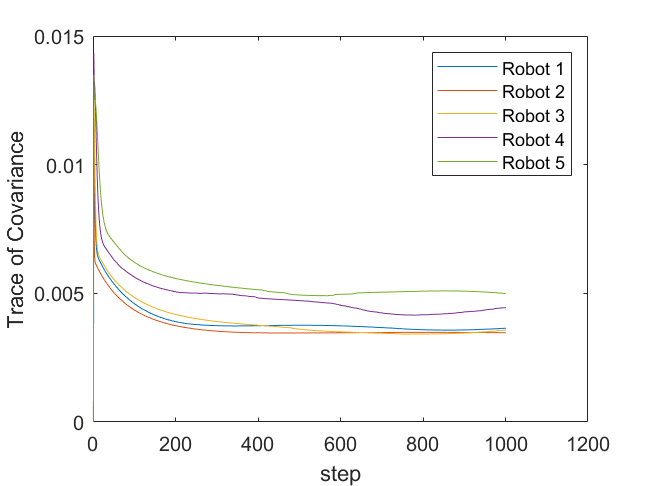

if(Method(1))
    len = size(TrPlist(1).P,2);
    
    figure()
    step = 1:len;
    plot(step, TrPlist(1).P(1,:), "DisplayName", 'Robot 1');hold on
    plot(step, TrPlist(2).P(1,:), "DisplayName", 'Robot 2');hold on
    plot(step, TrPlist(3).P(1,:), "DisplayName", 'Robot 3');hold on
    plot(step, TrPlist(4).P(1,:), "DisplayName", 'Robot 4');hold on
    plot(step, TrPlist(5).P(1,:), "DisplayName", 'Robot 5');hold on
    xlabel("step");
    ylabel('Trace of Covariance');
legend
end

### Method 2: Use InEKF to combine all the measurement

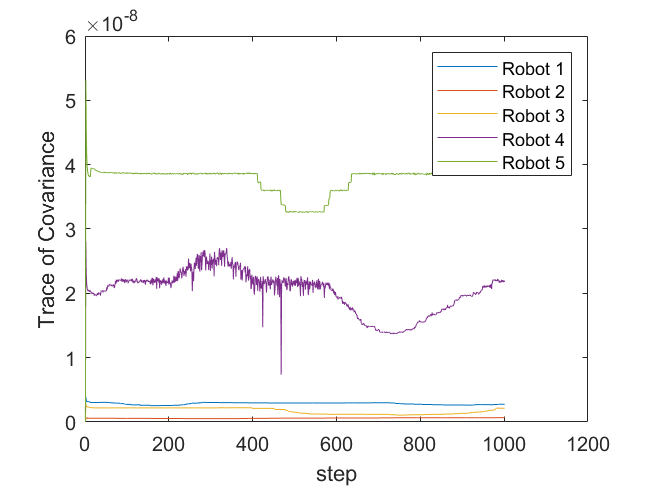

debug=0;

W_list = [];
TrPlist=[];
if(Method(2))
    %-------- INITIALIZE -------------
    N_imu=1;
    N_mea=2;
    N_update=1;
    t_update_set(N_update)=0;
    N_update_set(N_update)=1;
    for i=1:N_ROBOTS  
        X_init=initializer(i).X_init;
        method2(i).X(N_update)=X_init;     
        X_robots(i).X_last(N_imu).X=X_init;
        P_robots(i).P_last(N_imu).P=P_init;   
    end
   
    t_imu=Robot(1).IMU_data(N_imu).t;
    %-------- MAIN LOOP ---------------
    while(t_imu<T_WORKING)
        t_imu=Robot(1).IMU_data(N_imu).t; % Just use the 1st robot's timestamp
        %1. Independently propagate
        for i=1:N_ROBOTS
            X_last_i=X_robots(i).X_last(N_imu).X;
            P_last_i=P_robots(i).P_last(N_imu).P;
            IMU_data=Robot(i).IMU_data;
            acc_m=IMU_data(N_imu).a;
            w_m=IMU_data(N_imu).w;
            [X_pred, P_pred]=  inEKF_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
%             Note: once saving, should be saved as the next time dat
            X_robots(i).X_last(N_imu+1).X=X_pred;
            P_robots(i).P_last(N_imu+1).P=P_pred;
        end
        
        % detect measurements
        t_mea=m_data(N_mea).t;

        if(abs(t_imu-t_mea)<0.000000001)% meaning that receiving new measurements.
            N_update=N_update+1; % once receiving new measurements, conducting CI or KF update.

            X_update_tmp=[];
%%%%%%%%%%%%%%%%%%利用InEKF update去融合独立以及非独立的观测

            for i=1:5
                % %%%%%  Step1: 利用InEKF去融合非独立测量
                method2(i).X(N_update)=X_robots(i).X_last(N_imu+1).X;
                T_mea_neighbor=m_data(N_mea).robot(i).m_inter;
                real_Neighbornumber=length(find(A(i,:)))-1; % number of neighbors (denote j) of i. (without i itself)
                tmp_landmarks=[];%把邻居的先验估计，当作object landmark pose
                T_mea_relative=[];
                nn=1; %对于邻居的个数进行计数
                for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                    j=m_data(N_mea).robot(i).index(j_index); %利用j的index去拿出邻居的编号
                    %%%%建立相对测量的landmark list
                    tmp_landmarks(nn).T=eye(4,4);
                    tmp_landmarks(nn).T(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                    tmp_landmarks(nn).T(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                    %%%%%建立相对测量
                    T_mea_relative(nn).T=T_mea_neighbor(j_index).m;
                    T_mea_relative(nn).index=nn;
                    nn=nn+1;
                end
                sigma_now=sigma_ij(i);
                num_see_feature=real_Neighbornumber; %相对测量的数量即邻居数量捏
                X_pred=X_robots(i).X_last(N_imu+1).X; % after prediction
                P_pred=P_robots(i).P_last(N_imu+1).P;
                [X_update, P_update]=inEKF_X_iter_update(X_pred, P_pred, tmp_landmarks, T_mea_relative, sigma_now, num_see_feature,itermax);
                P_update=(P_update+P_update')/2; %保持协方差矩阵的对称性和正定性

                %%%%%%%%%%% Step2: 利用InEKF去融合环境观测%%%%%%%%%%%%%%%%%
                X_pred=X_update;
                P_pred=P_update; %先把上一步的值取出来
                T_mea_feature=m_data(N_mea).robot(i).m_feature; %取出i此时看到的路标观测
                NUM_Only_SEE_feature=m_data(N_mea).robot(i).feature_flag;%一共获取了多少个环境观测
                sigma_now=sigma_if(i);
                [X_update,P_update]=inEKF_X_iter_update(X_pred, P_pred, landmarks, T_mea_feature, sigma_now, NUM_Only_SEE_feature,itermax);
                P_update=(P_update+P_update')/2; %保持协方差矩阵的对称性和正定性
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                %%%%%robot i更新之后，还不能直接更新到整体的数据结构之中，暂时存下来。
                X_update_tmp(i).X=X_update;          
                P_robots(i).P_last(N_imu+1).P=P_update;   
                method2(i).X(N_update)=X_update; 
                TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).P(1:6,1:6));
            end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
            %%%%%%%%%%本版本种这一部分被封印起来哩1!%%%%%%%%%%%%%%%%%%%%
            if(0)
                for i=1:5 %遍历每个机器人
                    T_mea_feature=m_data(N_mea).robot(i).m_feature; %取出i此时看到的路标观测
                    T_mea_neighbor=m_data(N_mea).robot(i).m_inter;
                    NUM_i_observe_feature=length(T_mea_feature);%一共看到了多少个features
                    nn=1;%对于邻居的个数进行计数
                    real_Neighbornumber=length(find(A(i,:)))-1; % number of neighbors (denote j) of i. (without i itself)
                    est_xi=zeros(6,real_Neighbornumber);
                    P_est_by_j=zeros(6,6,real_Neighbornumber);
                    tmp_landmarks=[];
                    
                    NUM_Only_SEE_feature=m_data(N_mea).robot(i).feature_flag;
                    
                    for mm=1:N_LANDMARKS
                        tmp_landmarks(mm).T=landmarks(mm).T;
                    end
                    %--start "namespace: robot i"--
                    %把邻居自己的估计值当作一个landmark"真值"，加入到landmark list之中
                    for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                        j=m_data(N_mea).robot(i).index(j_index);
                        tmp_landmarks(N_LANDMARKS+nn).T=eye(4,4);
                        tmp_landmarks(N_LANDMARKS+nn).T(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                        tmp_landmarks(N_LANDMARKS+nn).T(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                
                        T_mea_feature(NUM_i_observe_feature+nn).T=T_mea_neighbor(j_index).m;
                        T_mea_feature(NUM_i_observe_feature+nn).index=N_LANDMARKS+nn;
                        nn=nn+1;
                    end
                    sigma_all=[sigma_if(i);sigma_ij(i)];
                    num_see_feature=NUM_i_observe_feature+real_Neighbornumber; %一共收到了多少测量，包括相对测量和绝对
                    X_pred=X_robots(i).X_last(N_imu+1).X; % after CI
                    P_pred=P_robots(i).P_last(N_imu+1).P;
                    [X_update,P_update]=inEKF_mix_iter_update(X_pred, P_pred, tmp_landmarks, T_mea_feature, sigma_all, num_see_feature,itermax,NUM_Only_SEE_feature,debug);
                    P_update=(P_update+P_update')/2; %保持协方差矩阵的对称性和正定性
    % 更新之后需要先将状态暂存下来，因为其他邻居用的是预测后的量，不能有的更新了，有的没有更新！             
    %               
    % if update, rewrite.
                    X_update_tmp(i).X=X_update;
               
                    P_robots(i).P_last(N_imu+1).P=P_update;
                    method2(i).X(N_update)=X_update; 
                    TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).P(1:6,1:6));
                end
            end
            for i=1:5
                X_robots(i).X_last(N_imu+1).X=X_update_tmp(i).X;
            end
            N_update_set(N_update)=N_imu;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;
        end
        N_imu=N_imu+1;
    end
    %保存结果
    actin=actin+1;
    activatedmethod(actin).methodname='InEKF';
    activatedmethod(actin).result=method2;
end

if(Method(2))
    len = size(TrPlist(1).P,2);
    figure()
    step = 1:len;
    plot(step, TrPlist(1).P(1,:), "DisplayName", 'Robot 1');hold on
    plot(step, TrPlist(2).P(1,:), "DisplayName", 'Robot 2');hold on
    plot(step, TrPlist(3).P(1,:), "DisplayName", 'Robot 3');hold on
    plot(step, TrPlist(4).P(1,:), "DisplayName", 'Robot 4');hold on
    plot(step, TrPlist(5).P(1,:), "DisplayName", 'Robot 5');hold on
    xlabel("step");
    ylabel('Trace of Covariance');
    legend
end

### Method 3: Iterated InEKF + Fast Covariance Intersection.

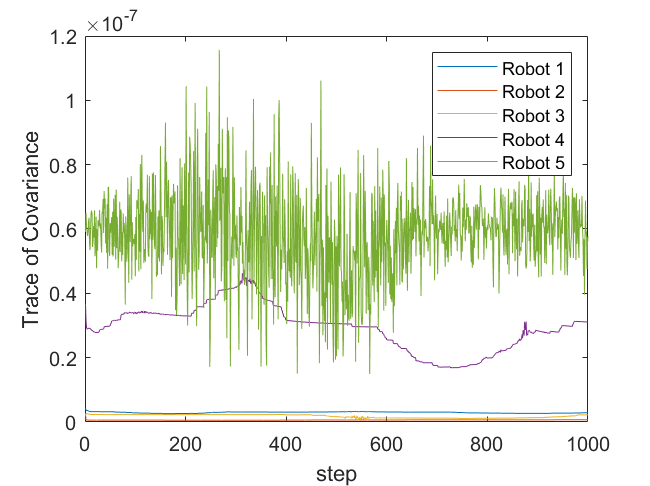

W_list = [];
TrPlist=[];
if(Method(3))
    %%-------- INITIALIZE -------------
    N_imu=1;
    N_mea=2;
    N_update=1;
    t_update_set(N_update)=0;
    N_update_set(N_update)=1;
    for i=1:N_ROBOTS  
        X_init=initializer(i).X_init;
        method3(i).X(N_update)=X_init;     
        X_robots(i).X_last(N_imu).X=X_init;
        P_robots(i).P_last(N_imu).P=P_init;   
    end
   
    t_imu=Robot(1).IMU_data(N_imu).t;
    %%-------- MAIN LOOP ---------------
    while(t_imu<T_WORKING)
        t_imu=Robot(1).IMU_data(N_imu).t; % Just use the 1st robot's timestamp
        %%1. Independently propagate
        for i=1:N_ROBOTS
            X_last_i=X_robots(i).X_last(N_imu).X;
            P_last_i=P_robots(i).P_last(N_imu).P;
            IMU_data=Robot(i).IMU_data;
            acc_m=IMU_data(N_imu).a;
            w_m=IMU_data(N_imu).w;
            [X_pred, P_pred]=  inEKF_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
            %Note: once saving, should be saved as the next time dat
            X_robots(i).X_last(N_imu+1).X=X_pred;
            P_robots(i).P_last(N_imu+1).P=P_pred;
        end

        %% detect measurements
        t_mea=m_data(N_mea).t;
        if(abs(t_imu-t_mea)<0.000000001)% meaning that receiving new measurements.
            N_update=N_update+1; % once receiving new measurements, conducting CI or KF update.
            %% 2.Using CI to fuse the dependent estimates
            method3(i).X(N_update)=X_robots(i).X_last(N_imu+1).X;

            if(1)
            for i=1:5 % choose robot i.
          
                nn=1;
                real_Neighbornumber=length(find(A(i,:)))-1; % number of neighbors (denote j) of i. (without i itself)
                est_xi=zeros(6,real_Neighbornumber);
                P_est_by_j=zeros(6,6,real_Neighbornumber);
                % --start "namespace: robot i"--
                
                for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                    
                   j=m_data(N_mea).robot(i).index(j_index); % which j
                   Robot_mea_now=m_data(N_mea).robot(j); % Take out j's relative observation
                   
                   index_list_j=Robot_mea_now.index;
                   i_index = find(index_list_j==i);
                   X_m_i_in_j=Robot_mea_now.m_inter(i_index).m;
       
                   X_j_prior=eye(4,4);
                   X_j_prior(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                   X_j_prior(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                   X_i_prior=eye(4,4);
                   X_i_prior(1:3,1:3)=X_robots(i).X_last(N_imu+1).X(1).Rimu;
                   X_i_prior(1:3,4)=X_robots(i).X_last(N_imu+1).X(1).pimu';
                   X_i_est_by_j=X_j_prior * X_m_i_in_j;

                   inv_X_i_prior = invT(X_i_prior);
                   inv_X_i_est_by_j = invT(X_i_est_by_j); 
                   xi_now=se3_log(X_i_prior * inv_X_i_est_by_j);
                   est_xi(:,nn)=xi_now; 
                      
                   inv_X_i_in_j_mea=invT(X_m_i_in_j);
                   R_ji=sigma_ij(j)*sigma_ij(j)*eye(6);
                   
                    
                   AdxJ = Adx(X_j_prior);
                   Theta =AdxJ * sigma_ij(j) *ones(6,1);
                   H_j = inv(jacobian_left(Theta));
                   H_Rij = AdxJ;

                   P_est_res_now=P_robots(j).P_last(N_imu).P(1:6,1:6)  + H_Rij  *R_ji * H_Rij';
       
                   P_est_by_j(:,:,nn)=(P_est_res_now+P_est_res_now')/2;
                   nn=nn+1;
                    
                end
    
                %%%%%先融合观测们，再把融合结果和先验融合在一起%%%%%
                [xi_CI,P_CI, w]=fastCI(est_xi,P_est_by_j);
                a=zeros(15,1);
                cov_A = P_robots(i).P_last(N_imu+1).P;
                b = xi_CI;
                B = P_CI;

                H = zeros(15,6);
                H(1:6,1:6)=eye(6);
                [c,C,omega]=conventionalCI(a,cov_A,b,B,H');
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

                P_robots(i).P_last(N_imu+1).P=C;

                X_CI = se3_exp(-c(1:6,1))*X_i_prior;
                method3(i).X(N_update).Rimu=X_CI(1:3,1:3);
                method3(i).X(N_update).pimu=X_CI(1:3,4)';
                X_robots(i).X_last(N_imu+1).X(1).Rimu=X_CI(1:3,1:3); % if CI, rewrite.
                X_robots(i).X_last(N_imu+1).X(1).pimu=X_CI(1:3,4)';
            end
        end
            %% 3. Using KF to update feature measurement.
            for i=1:N_ROBOTS
                mea_now=m_data(N_mea).robot(i);
                % --start "namespace: robot i"--
                num_see_feature=m_data(N_mea).robot(i).feature_flag;
                T_mea_feature=m_data(N_mea).robot(i).m_feature; 
                X_update=X_robots(i).X_last(N_imu+1).X;
                if(num_see_feature)% only if seeing the feature, would the robot update
                    X_pred=X_robots(i).X_last(N_imu+1).X; % after CI
                    P_pred=P_robots(i).P_last(N_imu+1).P;
                    [X_update,P_update]=inEKF_X_iter_update(X_pred, P_pred, landmarks, T_mea_feature, sigma_if(i), num_see_feature,itermax);
                    P_update=(P_update+P_update')/2;
                    % if update, rewrite.
                    X_robots(i).X_last(N_imu+1).X=X_update;
                    X_robots(i).X_last(N_imu+1).X=X_update;

                    P_robots(i).P_last(N_imu+1).P=P_update;
                    method3(i).X(N_update)=X_update;
                end
                method3(i).X(N_update)=X_update;
                % --end "namespace: robot i"--
                 TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).P(1:6,1:6));
            end
            
            N_update_set(N_update)=N_imu;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;

        end
        N_imu=N_imu+1;
    end
actin=actin+1;
activatedmethod(actin).methodname='InCI-EKF';
activatedmethod(actin).result=method3;
end

if(Method(3))
    figure()
    len = size(TrPlist(1).P,2);
    step = 1:len-1;
    
    plot(step, TrPlist(1).P(1,2:end), "DisplayName", 'Robot 1');hold on
    plot(step, TrPlist(2).P(1,2:end), "DisplayName", 'Robot 2');hold on
    plot(step, TrPlist(3).P(1,2:end), "DisplayName", 'Robot 3');hold on
    plot(step, TrPlist(4).P(1,2:end), "DisplayName", 'Robot 4');hold on
    plot(step, TrPlist(5).P(1,2:end), "DisplayName", 'Robot 5');hold on
        xlabel("step");
    ylabel('Trace of Covariance');
    legend
end

### Method 4: standard EKF (SO(3)-SLAM)


W_list = [];
TrPlist=[];
if(Method(4))
    %-------- INITIALIZE -------------
    N_imu=1;
    N_mea=2;
    N_update=1;
    t_update_set(N_update)=0;
    N_update_set(N_update)=1;
    for i=1:N_ROBOTS  
        X_init=initializer(i).X_init;
        method4(i).X(N_update)=X_init;     
        X_robots(i).X_last(N_imu).X=X_init;
        P_robots(i).P_last(N_imu).P=P_init;   
    end
   
    t_imu=Robot(1).IMU_data(N_imu).t;
    %-------- MAIN LOOP ---------------
    while(t_imu<T_WORKING)
        t_imu=Robot(1).IMU_data(N_imu).t; % Just use the 1st robot's timestamp
        %1. Independently propagate
        for i=1:N_ROBOTS
            X_last_i=X_robots(i).X_last(N_imu).X;
            P_last_i=P_robots(i).P_last(N_imu).P;
            IMU_data=Robot(i).IMU_data;
            acc_m=IMU_data(N_imu).a;
            w_m=IMU_data(N_imu).w;
            [X_pred, P_pred]=  EKF_propagate(X_last_i, P_last_i, w_m, acc_m, dti, SIGMA_SET);
%             Note: once saving, should be saved as the next time dat
            X_robots(i).X_last(N_imu+1).X=X_pred;
            P_robots(i).P_last(N_imu+1).P=P_pred;
        end
        
        % detect measurements
        t_mea=m_data(N_mea).t;

        if(abs(t_imu-t_mea)<0.000000001)% meaning that receiving new measurements.
            N_update=N_update+1; % once receiving new measurements, conducting CI or KF update.
            X_update_tmp=[];
            %利用EKF update去融合独立以及非独立的观测

%%%%%%%%%%%%%%%%%%利用EKF update去融合独立以及非独立的观测

            for i=1:5
                % %%%%%  Step1: 利用InEKF去融合非独立测量
                method4(i).X(N_update)=X_robots(i).X_last(N_imu+1).X;
                T_mea_neighbor=m_data(N_mea).robot(i).m_inter;
                real_Neighbornumber=length(find(A(i,:)))-1; % number of neighbors (denote j) of i. (without i itself)
                tmp_landmarks=[];%把邻居的先验估计，当作object landmark pose
                T_mea_relative=[];
                nn=1; %对于邻居的个数进行计数
                for j_index=1:real_Neighbornumber % To get the measurement of j of i.
                    j=m_data(N_mea).robot(i).index(j_index); %利用j的index去拿出邻居的编号
                    %%%%建立相对测量的landmark list
                    tmp_landmarks(nn).T=eye(4,4);
                    tmp_landmarks(nn).T(1:3,1:3)=X_robots(j).X_last(N_imu+1).X(1).Rimu;
                    tmp_landmarks(nn).T(1:3,4)=X_robots(j).X_last(N_imu+1).X(1).pimu';
                    %%%%%建立相对测量
                    T_mea_relative(nn).T=T_mea_neighbor(j_index).m;
                    T_mea_relative(nn).index=nn;
                    nn=nn+1;
                end
                sigma_now=sigma_ij(i);
                num_see_feature=real_Neighbornumber; %相对测量的数量即邻居数量捏
                X_pred=X_robots(i).X_last(N_imu+1).X; % after prediction
                P_pred=P_robots(i).P_last(N_imu+1).P;
                [X_update, P_update]=EKF_X_iter_update(X_pred, P_pred, tmp_landmarks, T_mea_relative, sigma_now, num_see_feature,itermax);
                P_update=(P_update+P_update')/2; %保持协方差矩阵的对称性和正定性

                %%%%%%%%%%% Step2: 利用EKF去融合环境观测%%%%%%%%%%%%%%%%%
                X_pred=X_update;
                P_pred=P_update; %先把上一步的值取出来
                T_mea_feature=m_data(N_mea).robot(i).m_feature; %取出i此时看到的路标观测
                NUM_Only_SEE_feature=m_data(N_mea).robot(i).feature_flag;%一共获取了多少个环境观测
                sigma_now=sigma_if(i);
                [X_update,P_update]=EKF_X_iter_update(X_pred, P_pred, landmarks, T_mea_feature, sigma_now, NUM_Only_SEE_feature,itermax);
                P_update=(P_update+P_update')/2; %保持协方差矩阵的对称性和正定性
                %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
                %%%%%robot i更新之后，还不能直接更新到整体的数据结构之中，暂时存下来。
                X_update_tmp(i).X=X_update;          
                P_robots(i).P_last(N_imu+1).P=P_update;   
                method4(i).X(N_update)=X_update; 
                TrPlist(i).P(N_update)=trace(P_robots(i).P_last(N_imu+1).P(1:6,1:6));
            end
          
            for i=1:5
                X_robots(i).X_last(N_imu+1).X=X_update_tmp(i).X;
            end
            N_update_set(N_update)=N_imu;
            t_update_set(N_update)=t_mea;
            N_mea=N_mea+1;
        end
        N_imu=N_imu+1;
    end
    %保存结果
    actin=actin+1;
    activatedmethod(actin).methodname='EKF';
    activatedmethod(actin).result=method4;
end


####  The real path all will be used in evaluation.

real_path_all=[];
for i=1:N_ROBOTS
    real_path=Robot(i).real_path;
    real_path_select = filterArrayByIndex(real_path,N_update_set);
    real_path_all(i).rp=real_path_select;
end

### Evaluation and Plot

method 1


--------------/RMSE/-------------
Robots 


i = 1

Orientation(rad): 
Err_IMU_R | 4.0726e-05
Position(m):
Err_IMU_p | 0.00021404
--------------/RMSE/-------------
Robots 


i = 2

Orientation(rad): 
Err_IMU_R | 1.734e-05
Position(m):
Err_IMU_p | 0.00017738
--------------/RMSE/-------------
Robots 


i = 3

Orientation(rad): 
Err_IMU_R | 3.0166e-05
Position(m):
Err_IMU_p | 0.0002558
--------------/RMSE/-------------
Robots 


i = 4

Orientation(rad): 
Err_IMU_R | 0.00012731
Position(m):
Err_IMU_p | 0.00087949
--------------/RMSE/-------------
Robots 


i = 5

Orientation(rad): 
Err_IMU_R | 0.00017677
Position(m):
Err_IMU_p | 0.002048
============/Average RMSE/===========
Average Rotation RMSE among Robots: 
7.8463e-05
Average Position RMSE among Robots: 
0.00071495


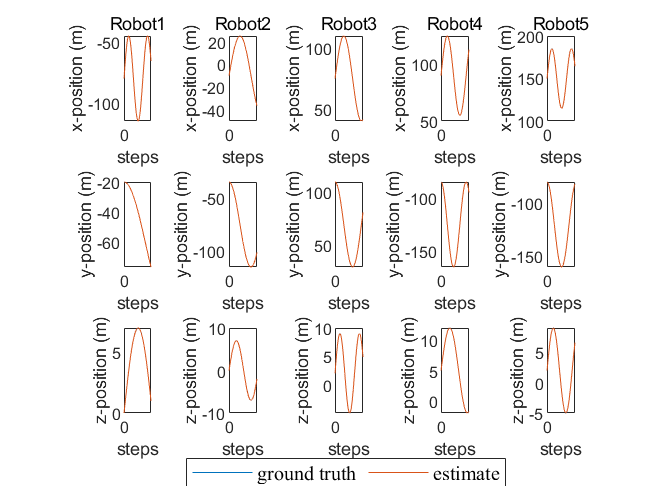

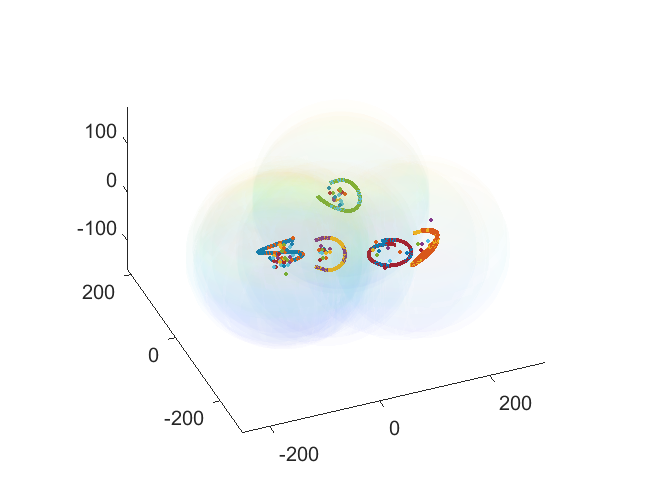

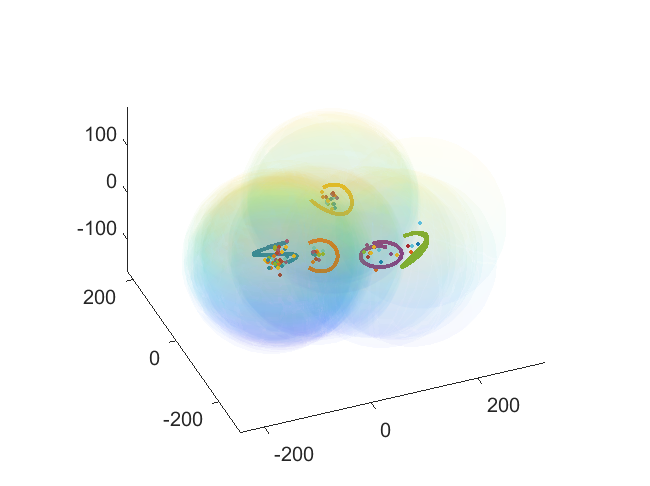


if(Method(1))
disp("method 1");
ATE(real_path_all, method1, landmarks, Eff_Range,1,datasetname);
end

method 2


--------------/RMSE/-------------
Robots 


i = 1

Orientation(rad): 
Err_IMU_R | 4.1545e-05
Position(m):
Err_IMU_p | 0.00079114
--------------/RMSE/-------------
Robots 


i = 2

Orientation(rad): 
Err_IMU_R | 2.6066e-05
Position(m):
Err_IMU_p | 0.0017881
--------------/RMSE/-------------
Robots 


i = 3

Orientation(rad): 
Err_IMU_R | 3.3693e-05
Position(m):
Err_IMU_p | 0.0017516
--------------/RMSE/-------------
Robots 


i = 4

Orientation(rad): 
Err_IMU_R | 0.00025
Position(m):
Err_IMU_p | 0.018483
--------------/RMSE/-------------
Robots 


i = 5

Orientation(rad): 
Err_IMU_R | 0.00028079
Position(m):
Err_IMU_p | 0.0092239
============/Average RMSE/===========
Average Rotation RMSE among Robots: 
0.00012642
Average Position RMSE among Robots: 
0.0064074


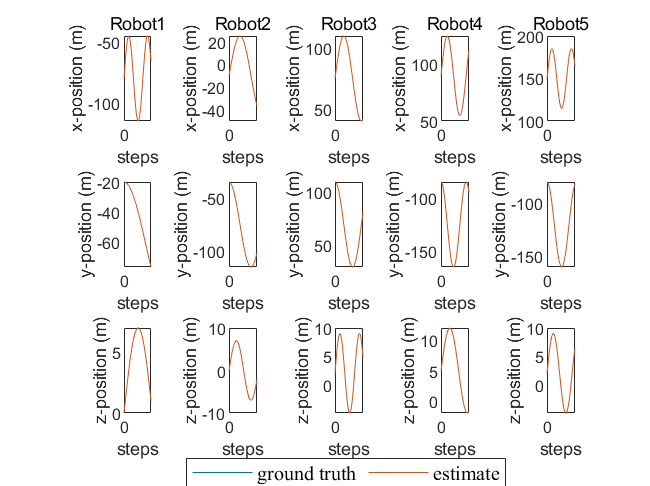

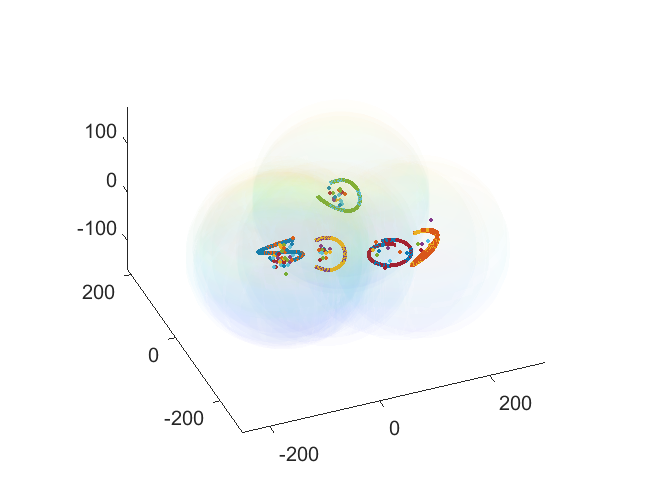


if(Method(2))
disp("method 2");
ATE(real_path_all, method2, landmarks, Eff_Range,2,datasetname);
end

method 3


--------------/RMSE/-------------
Robots 


i = 1

Orientation(rad): 
Err_IMU_R | 4.0545e-05
Position(m):
Err_IMU_p | 0.00010229
--------------/RMSE/-------------
Robots 


i = 2

Orientation(rad): 
Err_IMU_R | 1.713e-05
Position(m):
Err_IMU_p | 5.0071e-05
--------------/RMSE/-------------
Robots 


i = 3

Orientation(rad): 
Err_IMU_R | 2.9929e-05
Position(m):
Err_IMU_p | 8.2682e-05
--------------/RMSE/-------------
Robots 


i = 4

Orientation(rad): 
Err_IMU_R | 0.0001269
Position(m):
Err_IMU_p | 0.00026461
--------------/RMSE/-------------
Robots 


i = 5

Orientation(rad): 
Err_IMU_R | 0.0001757
Position(m):
Err_IMU_p | 0.00052678
============/Average RMSE/===========
Average Rotation RMSE among Robots: 
7.8041e-05
Average Position RMSE among Robots: 
0.00020529


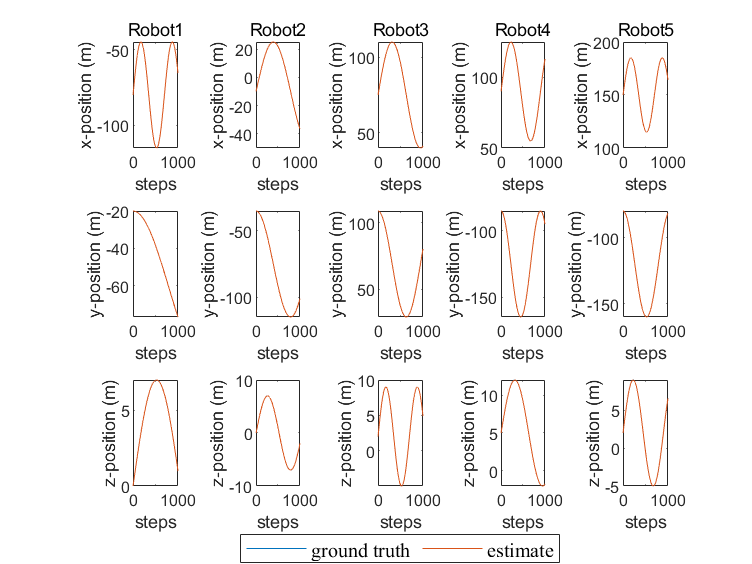

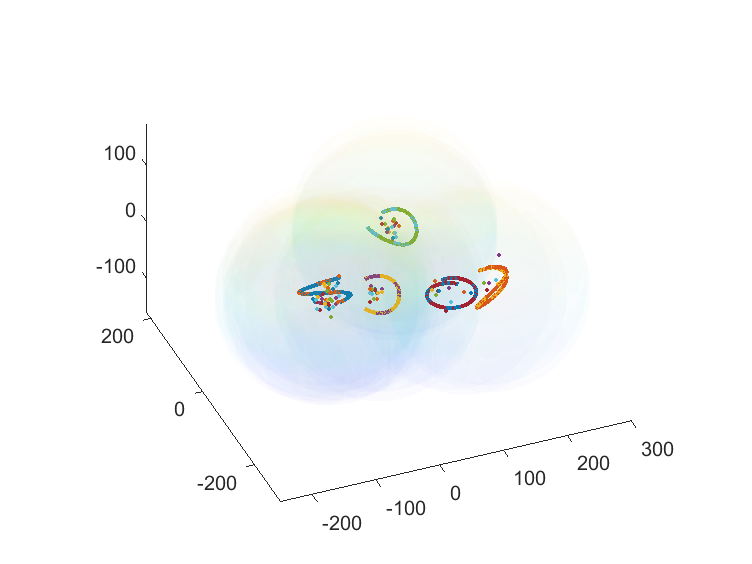


if(Method(3))
disp("method 3");
ATE(real_path_all, method3, landmarks, Eff_Range,3,datasetname);
end

method 4


--------------/RMSE/-------------
Robots 


i = 1

Orientation(rad): 
Err_IMU_R | 0.00014104
Position(m):
Err_IMU_p | 0.0030414
--------------/RMSE/-------------
Robots 


i = 2

Orientation(rad): 
Err_IMU_R | 4.7163e-05
Position(m):
Err_IMU_p | 0.0018366
--------------/RMSE/-------------
Robots 


i = 3

Orientation(rad): 
Err_IMU_R | 0.00014626
Position(m):
Err_IMU_p | 0.0042838
--------------/RMSE/-------------
Robots 


i = 4

Orientation(rad): 
Err_IMU_R | 0.00025085
Position(m):
Err_IMU_p | 0.008104
--------------/RMSE/-------------
Robots 


i = 5

Orientation(rad): 
Err_IMU_R | 0.0003842
Position(m):
Err_IMU_p | 0.0092616
============/Average RMSE/===========
Average Rotation RMSE among Robots: 
0.0001939
Average Position RMSE among Robots: 
0.0053055


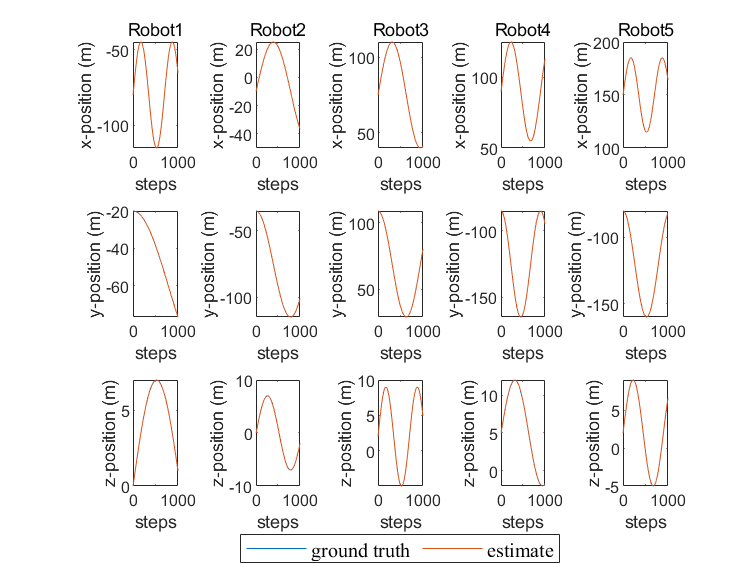

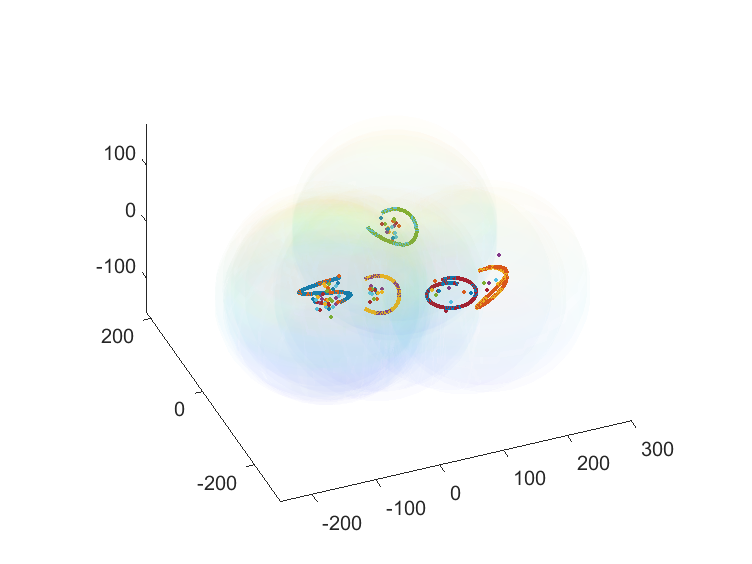


if(Method(4))
    disp("method 4");
    ATE(real_path_all, method4, landmarks, Eff_Range,4,datasetname);
end

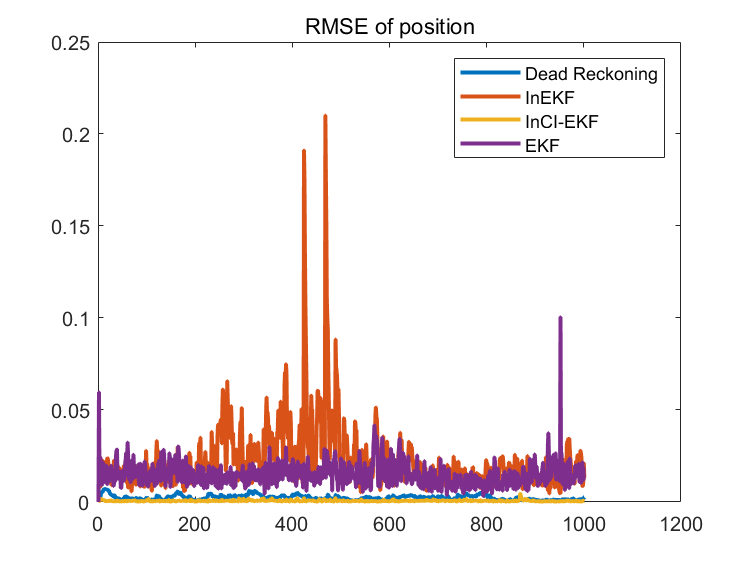

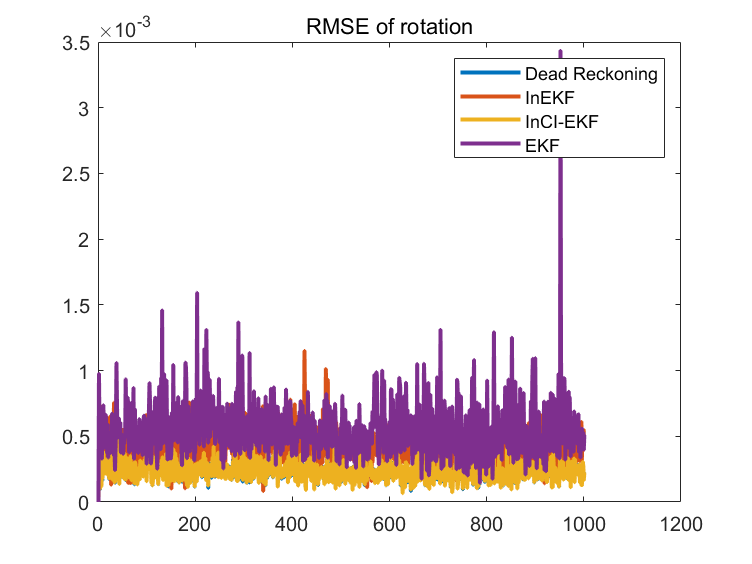

ATE_ALL(real_path_all,activatedmethod,actin,datasetname);